# Time Complexity

x = rand(256,1);
X_FFT = fft(x);
X_loop = myDFTLoop(x);
X_matrix= myDFTMatrix(x);

%Norm-2 Difference:
loop_error = normest(X_FFT-X_loop);
matrix_error = normest(X_FFT - X_matrix);
fprintf("Loop Error: %4.2e",loop_error);

Loop Error: 4.32e-12

fprintf("Matrix Error: %4.2e",matrix_error);

Matrix Error: 4.37e-12

## Performance:

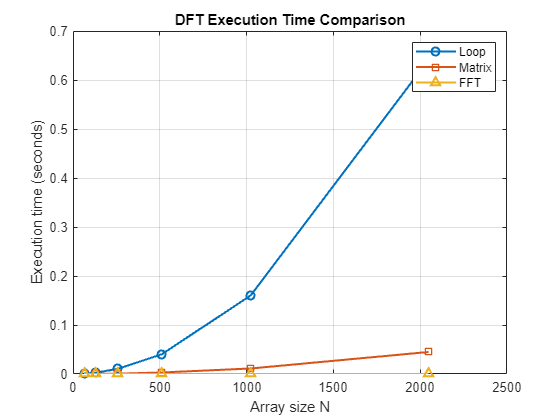

Nvals = [64 , 128, 256, 512, 1024, 2048];  
tLoop   = zeros(size(Nvals));
tMatrix = zeros(size(Nvals));
tFFT    = zeros(size(Nvals));

for k = 1:length(Nvals)
    N = Nvals(k);

    X1 = rand(1, N);

    tLoop(k) = timeit(@() myDFTLoop(X1));
    tMatrix(k) = timeit(@() myDFTMatrix(X1));
    tFFT(k) = timeit(@() fft(X1));
end
figure;
plot(Nvals, tLoop,   '-o', 'LineWidth', 1.5); hold on;
plot(Nvals, tMatrix, '-s', 'LineWidth', 1.5);
plot(Nvals, tFFT,    '-^', 'LineWidth', 1.5);
grid on;

xlabel('Array size N');
ylabel('Execution time (seconds)');
legend('Loop', 'Matrix', 'FFT');
title('DFT Execution Time Comparison'); hold off;

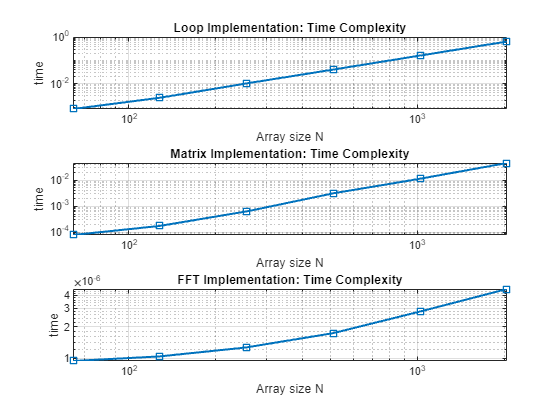

figure;
subplot(3,1,1);
loglog(Nvals, tLoop, '-s','LineWidth', 1.5); 
grid on;xlabel('Array size N');ylabel('time');title('Loop Implementation: Time Complexity');

subplot(3,1,2);
loglog(Nvals, tMatrix, '-s', 'LineWidth', 1.5); 
grid on;xlabel('Array size N');ylabel('time');title('Matrix Implementation: Time Complexity');

subplot(3,1,3);
loglog(Nvals, tFFT, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Array size N');
ylabel('time');
title('FFT Implementation: Time Complexity');

# Spectral Sampling

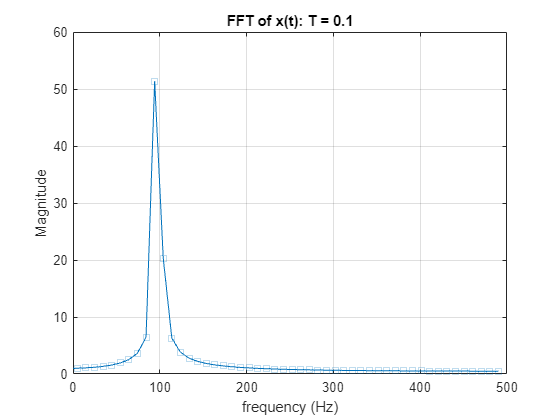

f1 = 100;
f2 = 105;
fs = 1000;
T = 0.1;
delta_t = 1/fs;
t = 0:delta_t:T;
x = cos(2*pi*f1.*t) + 0.5.*cos(2*pi*f2.*t); 
N = length(x);
freq = (-N/2:N/2-1)*(fs/N);
X = fftshift(fft(x));

figure;
subplot(1,1,1);
plot(freq, abs(X) , "-s");
title("FFT of x(t): T = 0.1");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0 500]);

## Zero-Padding:

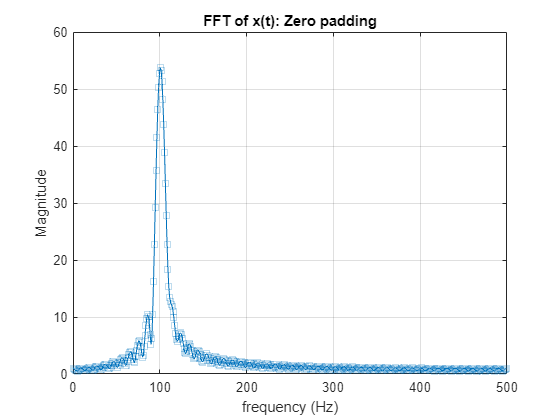

N_pad = 1024;
x = zeros(N_pad , 1);
x(1:N) =  cos(2*pi*f1.*t) + 0.5.*cos(2*pi*f2.*t); 
freq = (-N_pad/2:N_pad/2-1)*(fs/N_pad);
X = fftshift(fft(x));

figure;
subplot(1,1,1);
plot(freq, abs(X) , "-s");
title("FFT of x(t): Zero padding");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0,500]);

## Increase Observation Window:

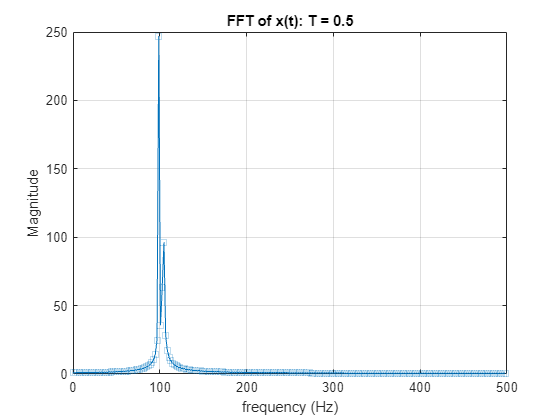

f1 = 100;
f2 = 105;
fs = 1000;
T = 0.5;
delta_t = 1/fs;
t = 0:delta_t:T;
x = cos(2*pi*f1.*t) + 0.5.*cos(2*pi*f2.*t); 
N = length(x);
freq = (-N/2:N/2-1)*(fs/N);
X = fftshift(fft(x));

figure;
subplot(1,1,1);
plot(freq, abs(X) , "-s");
title("FFT of x(t): T = 0.5");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0 500]);

## Spectral Leakage:

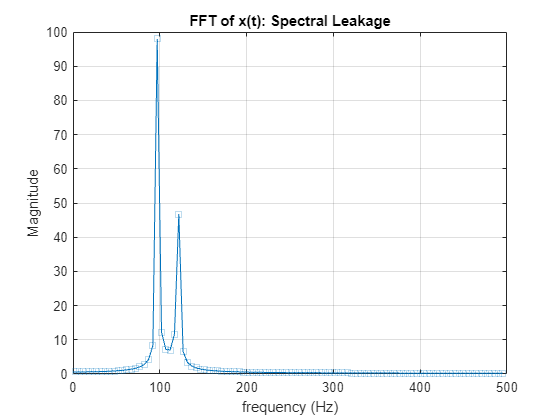

f1 = 100;
f2 = 123.5;
fs = 1000;
T = 0.2;
delta_t = 1/fs;
t = 0:delta_t:T;
x = cos(2*pi*f1.*t) + 0.5.*cos(2*pi*f2.*t); 
N = length(x);
freq = (-N/2:N/2-1)*(fs/N);
X = fftshift(fft(x));

figure;
subplot(1,1,1);
plot(freq, abs(X) , "-s");
title("FFT of x(t): Spectral Leakage");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0 500]);

## Hann

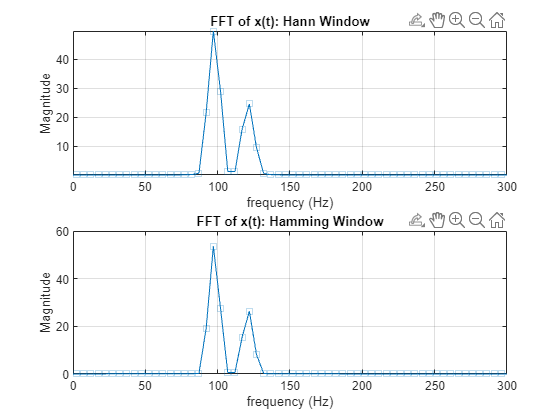

w_hann = hann(N)';
x_hann = x.*w_hann;
X_hann = fftshift(fft(x_hann));

w_hamming = hamming(N)';  
x_hamming = x .* w_hamming;
X_hamming = fftshift(fft(x_hamming));



figure;
subplot(2,1,1);
plot(freq, abs(X_hann) , "-s");
title("FFT of x(t): Hann Window");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0 300]);
subplot(2,1,2);
plot(freq , abs(X_hamming) , "-s");
title("FFT of x(t): Hamming Window");xlabel("frequency (Hz)");ylabel("Magnitude");grid on;xlim([0 300]);

clc;
clear;
close all;


n_x = 0:7;
x = n_x                

x =      0     1     2     3     4     5     6     7


n_h = 0:5;
h = (0.8).^n_h           

h =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277



y_lin = conv(x,h)

y_lin =          0    1.0000    2.8000    5.2400    8.1920   11.5536   15.2429   18.9322   14.6214   10.9107    7.6800    4.8333    2.2938


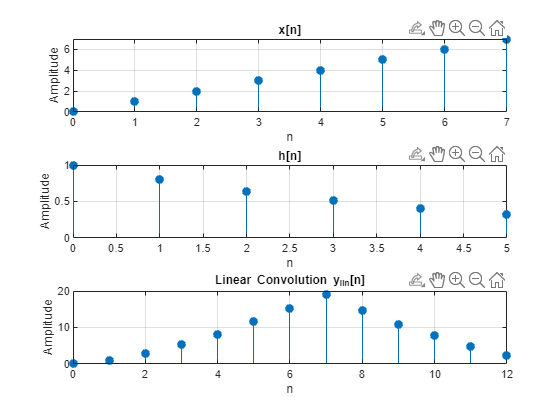


n_y = 0:(length(y_lin)-1);




figure;
subplot(3,1,1)
stem(n_x,x,'filled');
grid on;
title('x[n]');
xlabel('n');
ylabel('Amplitude');

subplot(3,1,2)
stem(n_h,h,'filled');
grid on;
title('h[n]');
xlabel('n');
ylabel('Amplitude');

subplot(3,1,3)
stem(n_y,y_lin,'filled');
grid on;
title('Linear Convolution y_{lin}[n]');
xlabel('n');
ylabel('Amplitude');

N1 = 8;
N2 = 14;

X8 = fft(x, N1);
H8 = fft(h, N1);
y_circ_8 = ifft(X8 .* H8);

X14 = fft(x, N2);
H14 = fft(h, N2);
y_circ_14 = ifft(X14 .* H14);

y_circ_8  = real(y_circ_8);
y_circ_14 = real(y_circ_14);

disp(y_circ_8)

   14.6214   11.9107   10.4800   10.0733   10.4858   11.5536   15.2429   18.9322




disp(y_circ_14)

    0.0000    1.0000    2.8000    5.2400    8.1920   11.5536   15.2429   18.9322   14.6214   10.9107    7.6800    4.8333    2.2938   -0.0000



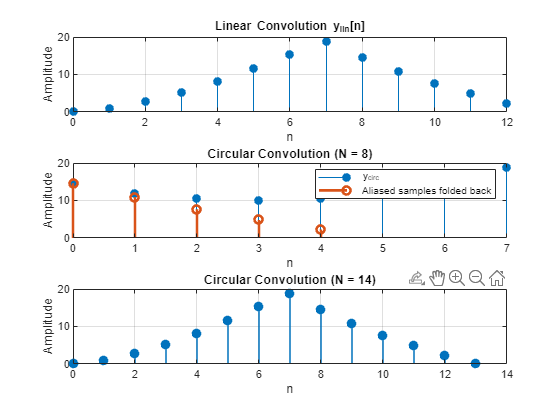



figure;


subplot(3,1,1)
stem(0:length(y_lin)-1, y_lin, 'filled')
grid on
xlabel('n');ylabel('Amplitude');title('Linear Convolution y_{lin}[n]')


subplot(3,1,2)

stem(0:N1-1, y_circ_8, 'filled')
hold on

alias_part = y_lin(N1+1:end);

stem(0:length(alias_part)-1,alias_part,'LineWidth',2)

grid on
title('Circular Convolution (N = 8)');xlabel('n');ylabel('Amplitude');
legend('y_{circ}','Aliased samples folded back')

subplot(3,1,3)
stem(0:N2-1, y_circ_14, 'filled','LineWidth',1.2)
grid on
title('Circular Convolution (N = 14)');xlabel('n');ylabel('Amplitude')

# Two-Dimensional DFT

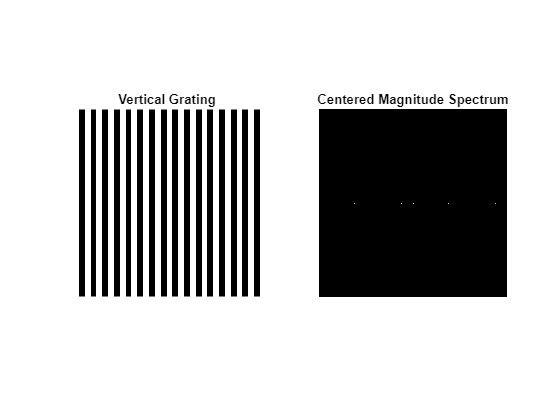

N = 256;

img1 = zeros(N,N);

for col = 1:N
    if mod(floor((col-1)/8),2)==0
        img1(:,col) = 1;
    end
end

%% 2D DFT
F1 = fft2(img1);
F1_shift = fftshift(F1);

mag1 = log(1 + abs(F1_shift));

figure;

subplot(1,2,1)
imshow(img1)
title('Vertical Grating')

subplot(1,2,2)
imshow(mat2gray(mag1))
title('Centered Magnitude Spectrum')

## b)

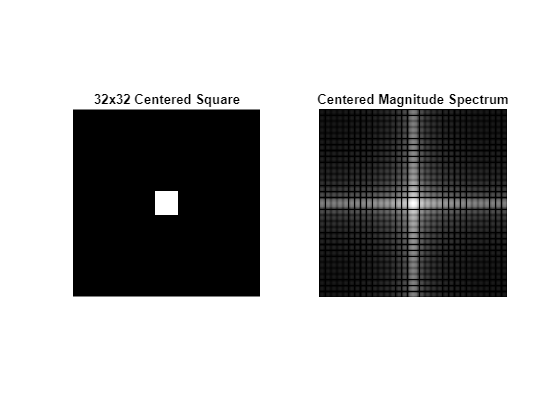

img2 = zeros(N,N);

center = N/2;
halfSide = 16;

img2(center-halfSide+1:center+halfSide,...
     center-halfSide+1:center+halfSide) = 1;

F2 = fftshift(fft2(img2));

mag2 = log(1 + abs(F2));

figure;
subplot(1,2,1)
imshow(img2)
title('32x32 Centered Square')

subplot(1,2,2)
imshow(mat2gray(mag2))
title('Centered Magnitude Spectrum')

## C)

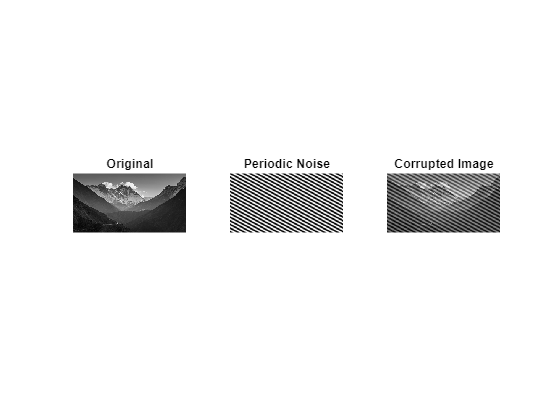

rgb = imread('mountain-3.jpg');
gray = rgb2gray(rgb);
gray = im2double(gray);

[M,N] = size(gray);
[x,y] = meshgrid(0:N-1,0:M-1);

u0 = 0.08;
v0 = 0.12;

noise = 0.4*cos(2*pi*(u0*x + v0*y));
corrupted = gray + noise;


figure;
subplot(1,3,1)
imshow(gray,[])
title('Original')

subplot(1,3,2)
imshow(noise,[])
title('Periodic Noise')

subplot(1,3,3)
imshow(corrupted,[])
title('Corrupted Image')

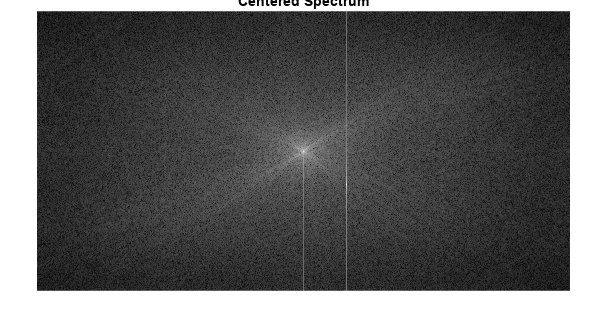

F = fftshift(fft2(corrupted));

magF = log(1 + abs(F));

figure;
imshow(mat2gray(magF))
title('Centered Spectrum')

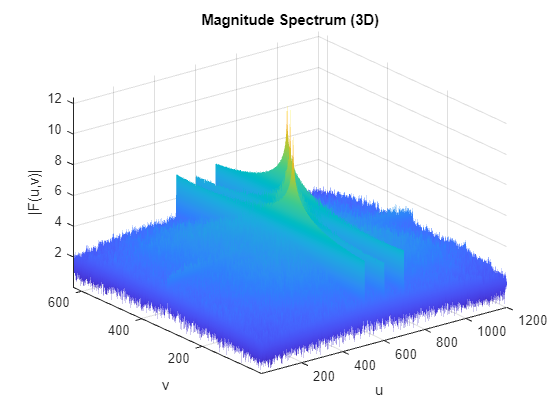



figure;

surf(magF)

shading interp
axis tight

xlabel('u')
ylabel('v')
zlabel('|F(u,v)|')

title('Magnitude Spectrum (3D)')

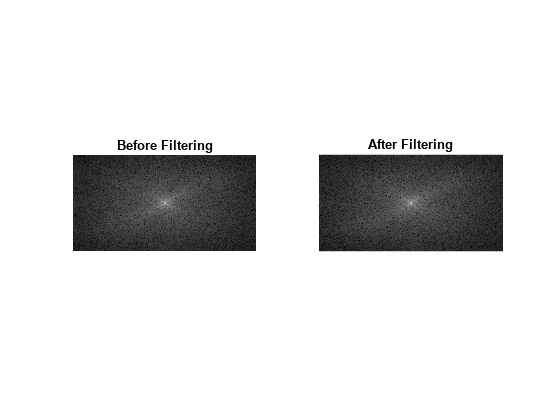

H = ones(M,N);

r = 2;

u1 = 300;
v1 = 600;


for i = 1:M
    for j = 1:N

        d1 = sqrt((i-u1)^2 + (j-v1)^2);
        d2 = sqrt((i-u2)^2 + (j-v2)^2);

        if d1 <= r || d2 <= r
            H(i,j) = 0;
        end

    end
end
F_filtered = F .* H;


figure

subplot(1,2,1)
imshow(mat2gray(log(1+abs(F))))
title('Before Filtering')

subplot(1,2,2)
imshow(mat2gray(log(1+abs(F_filtered))))
title('After Filtering')

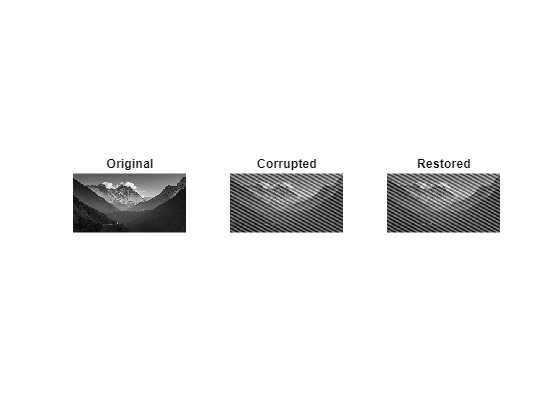

restored = real(ifft2(ifftshift(F_filtered)));


figure

subplot(1,3,1)
imshow(gray,[])
title('Original')

subplot(1,3,2)
imshow(corrupted,[])
title('Corrupted')

subplot(1,3,3)
imshow(restored,[])
title('Restored')

function X = myDFTLoop(x)
    N = length(x);
    X = zeros(N,1);
    for k=1:N
        for i = 0:N-1
            X(k) = X(k) + x(i+1).*exp(-1j.*2*pi./N.*(k-1).*i);
        end
    end
end

function X = myDFTMatrix(x)
    N = length(x);
    n = 0:N-1;
    W = exp(-1j * 2 *pi / N *(n'*n));
    X = W * x(:);
end